# 3F3 Lab Report.

- **Harry Sarson - 31/10/17**

- **Pembroke College**

## Definition of Global Variables

N = 10000;

global graph_max t;

graph_max = 1.3;
t = linspace(-3, 4, 100);

## 2.1 Uniform and normal Variables

gaussian_values = randn(N, 1);
gaussian_pdf = @(x) exp(-x.^2 / 2) / sqrt(2 * pi);
uniform_values = rand(N, 1) - 0.5;
uniform_pdf = @(x) 1 * (abs(x) < 0.5);

Scaled histogram of gaussian random numbers overlaid on the gaussian probability density function:

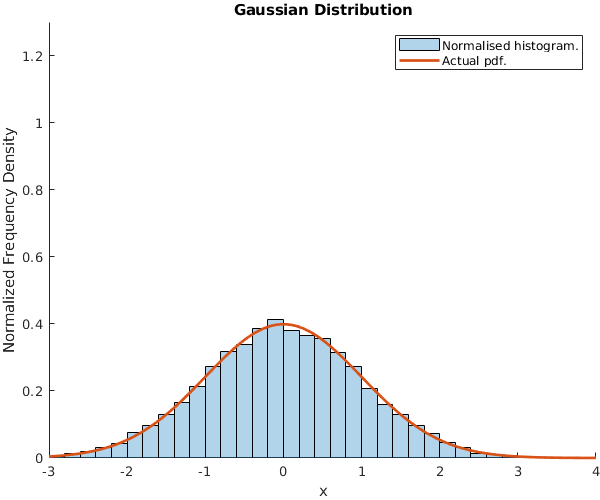

figure;
plot_histogram(gaussian_values, gaussian_pdf);
title('Gaussian Distribution');
print_fig('figures/gaussian-histogram');

Scaled histogram of uniform random numbers overlaid on the uniform probability density function:

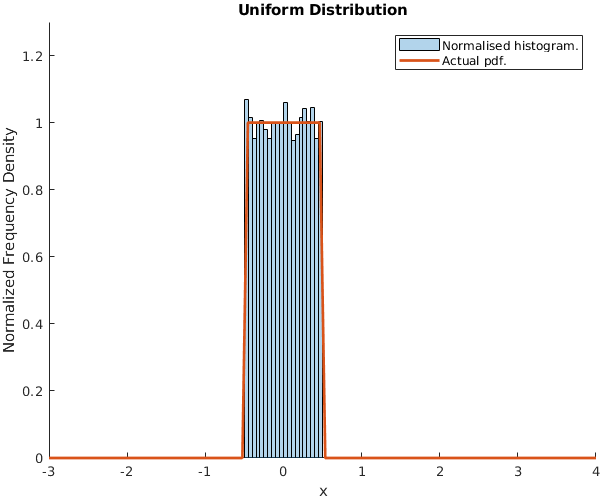

figure;
plot_histogram(uniform_values, uniform_pdf);
title('Uniform Distribution');
print_fig('figures/uniform-histogram');

Kernel density estimate for Gaussian random numbers overlaid on the gaussian probability density function:

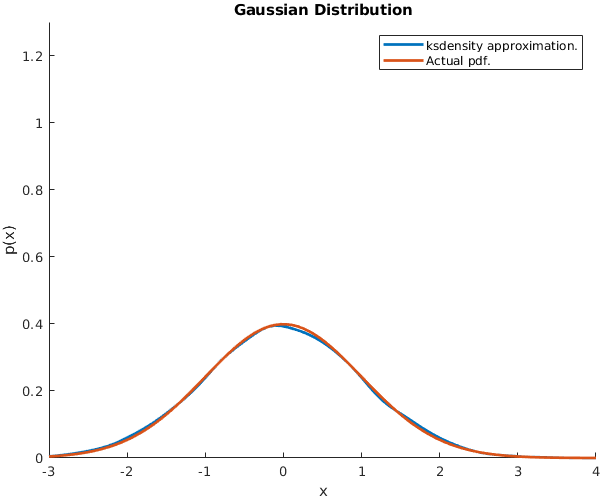

figure;
plot_ksdensity(gaussian_values, gaussian_pdf);
title('Gaussian Distribution');
print_fig('figures/gaussian-ksdensity');

Kernel density estimate for Uniform random numbers overlaid on the uniform probability density function:

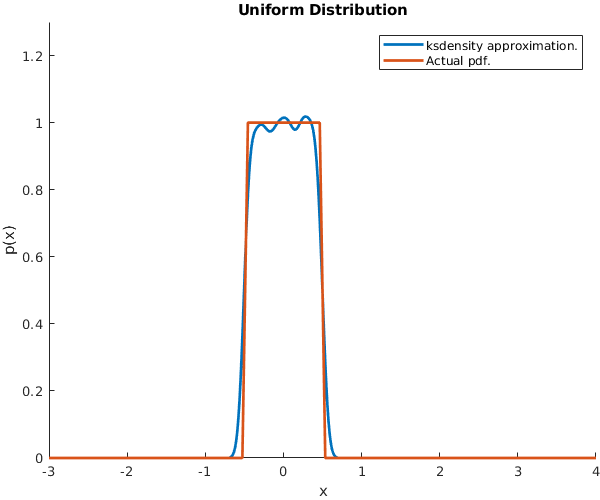

figure;
plot_ksdensity(uniform_values, uniform_pdf);
title('Uniform Distribution');
print_fig('figures/uniform-ksdensity');

The `ksdensity` method is effective if the pdf is smooth (for example a guassian pdf) but  is unsuitable for pdf's including discontinuities which it overly smooths. This is because the `ksdensity`'s use of gaussian kernals causes it to act a a low pass filter and therefore cannot be used with pdf's containing high frequencies (i.e. discontinuities).

n = 10.^[2,3,4];
axes = 0 * n;

For a uniform distribution the histogram count data (the heights of unormalised bars on a histogram plot) will be multinomially distributed. The probability $p_j
$ of a sample $x^{(i)}$ lying in a bin is equal to the width of the bin divided by the total width of the distribution, therefore $p_j = 1/J$where $J$is the number of bins.

For a histogram of $N$samples of a uniform random variable.

The mean bar height $\mu = NJ$.

The variance in bar height $\sigma^2 = NJ(1-J)$.

figure;
hold on;

for i = 1:length(n)
    axes(i) = subplot(1,length(n),i);
    h = histogram(rand(n(i), 1) - 0.5);    
    mean = n(i) / h.NumBins;
    std_dev = sqrt(mean * (1 - 1 / h.NumBins));
    
    line_heights = mean + std_dev * [3; 1; -1; -3];
    
    line([-1, 0.7], repelem(line_heights, 1, 2), ...
        'LineStyle', '--', ...
        'Color', 'black');
    
    line([-1, 0.7], [mean mean], 'Color', 'black');
    
    text([0.7 0.7], line_heights(1:2), ['μ+3σ'; 'μ+σ ']);
    text(0.7, mean, 'μ');
    
    set(gca, 'Box', 'off');
    ylim([0 mean * 1.7]);
    
    fprintf('For N = %i the mean of bar heights μ = %g and the variance in bar heights σ² = %g\n', ...
        n(i), mean, std_dev^2);
end

For N = 100 the mean of bar heights μ = 16.6667 and the variance in bar heights σ² = 13.8889
For N = 1000 the mean of bar heights μ = 100 and the variance in bar heights σ² = 90
For N = 10000 the mean of bar heights μ = 500 and the variance in bar heights σ² = 475


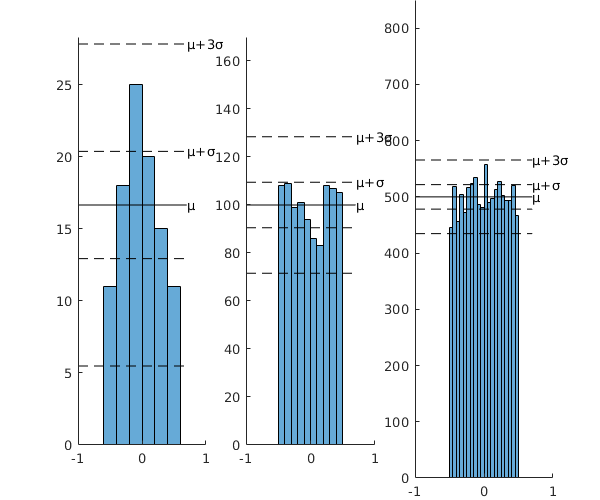


hold off;

print_fig('figures/uniform-bar-distribution');

The histogram bars are centred on the mean ($\mu$) and the variance of the bar heights ($\sigma^2
$) increase linearly with $N
$. Therefore, the standard deviation of bar height as a fraction of the total number of samples decreases which can be seen from the graph above as the bars are much more consistant in height for $N = 10^4
$ compared to $N = 10^2$.

## 2.2 Functions of Random Variables

For normally distributed $X \sim {\cal N}(x|0,1)$ random variables, take $y=f(X)=aX+b
$.


$$p(y) = \left.\frac{p(x)}{\frac{dy}{dx}}\right|_{x=f^{-1}(x)$$


$f(x) = ax + b$ and so $f^{-1}(y) = \frac{y - b}a$


$$p(y) = \frac{p\left(\frac{y - b}a\right)}a$$


Therefore $Y \sim {\cal N}(y|b, a^2)$. 

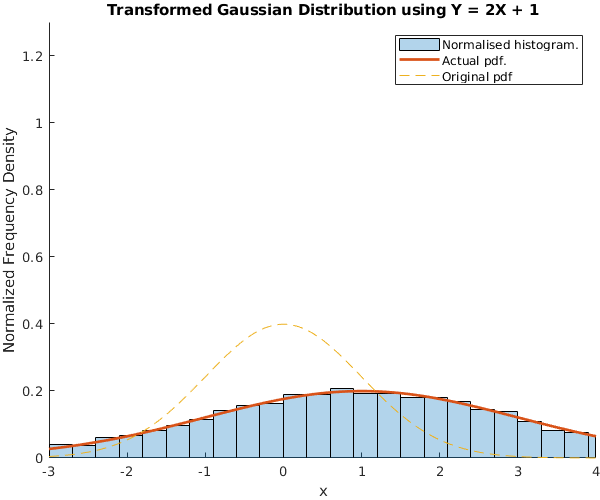

a = 2;
b = 1;

transformed_gaussian_values = a * gaussian_values + b;
transformed_gaussian_pdf = @(x) exp(-(x - b).^ 2 / (2 * a^2)) / (sqrt(2 * pi) * a);

figure
plot_histogram(transformed_gaussian_values, transformed_gaussian_pdf);
hold on;
plot(t, gaussian_pdf(t), '--', 'DisplayName', 'Original pdf');
title(sprintf('Transformed Gaussian Distribution using Y = %gX + %g', a, b));
hold off;
print_fig('figures/gaussian-linear-transform');

The graph shows histogramed values of $Y
$ overlayed with a guassian kernal $\mu = 1$and $\sigma = 2$. The histogrammed results strongly follow the anylitically calculated pdf.

Now take $X \sim p(x)={\cal N}(x|0,1)$ and $Y = f(X) = X^2$

$f(x) = x^2$ and so $\frac{dy}{dx} = 2x$ and $f^{-1}(y) = \pm \sqrt{y}$. Note $f^{-1}(y)$ is multi valued with ${f_1}^{-1}(y) = \sqrt{y}$ and ${f_2}^{-1}(y) = -\sqrt{y}$.


$$p_Y(y) = 
\left.\frac{p_X(x)}{\left|\frac{dy}{dx}\right|}\right|_{x={f_1}^{-1}(x)} + 
\left.\frac{p_X(x)}{\left|\frac{dy}{dx}\right|}\right|_{x={f_2}^{-1}(x)}$$



$$p_Y(y) = \frac{ p_X( \sqrt y ) }{ \left|2 \sqrt y \right| } + 
\frac{ p_X( -\sqrt y ) }{ \left|-2 \sqrt y \right| }$$


$P_Y(y) = \frac{ p_X( \sqrt y ) }{ \sqrt y }$ because $p_X(x)$ is an even function.

$Y
$ is a chi-squared distribution with one degree of freedom.

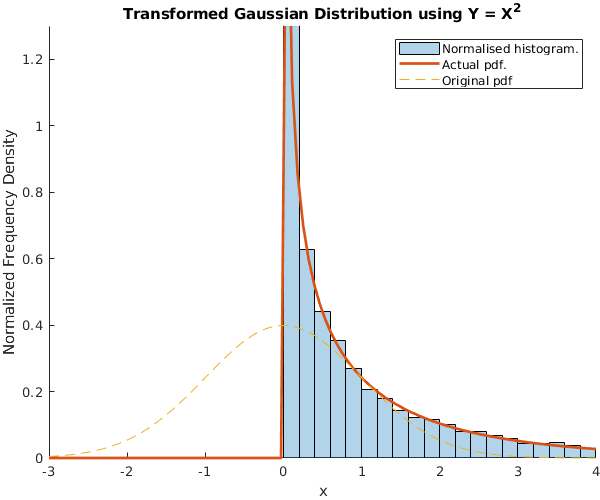

transformed_gaussian_values = gaussian_values.^2;
transformed_gaussian_pdf = @(x) exp(-x / 2) ./ (sqrt(x * 2* pi)) .* heaviside(x);

figure
plot_histogram(transformed_gaussian_values, transformed_gaussian_pdf);
hold on;
plot(t, gaussian_pdf(t), '--', 'DisplayName', 'Original pdf');
title('Transformed Gaussian Distribution using Y = X^2');
hold off;
print_fig('figures/gaussian-quadratic-transform');

The graph shows histogramed values of $Y
$ overlayed with plot of $\frac{ e^{ -x/2 } } { \sqrt{ 2 \pi x } }$. The histogrammed results strongly follow the anylitically calculated pdf.

## 2.3 Inverse CDF Method

For an exponential distribution with $\mu = 1$ the PDF $p_Y(y)$, CDF $F_y(y)
$ and inverse CDF ${F_Y}^{-1}(x)
$ are given by:

$p_Y(y) = e^{-y}$, $y \ge 0$. 


$$F_Y(y) = \int_{-\infty}^y p_Y(y) \, dy =  \int_0^y e^{-y} \, dy = 1 - e^{-y}$$



$${F_Y}^{-1}(x) =
\log{ \left( \frac 1 { 1 - x } \right)}$$



$$y^{(i)} = {F_Y}^{-1}(x^{(i)}) = 
\log \left( \frac 1 { 1 - x^{(i)} }  \right)$$


The following MATLAB code calculates samples of the exponential distribution using the inverse CDF method.

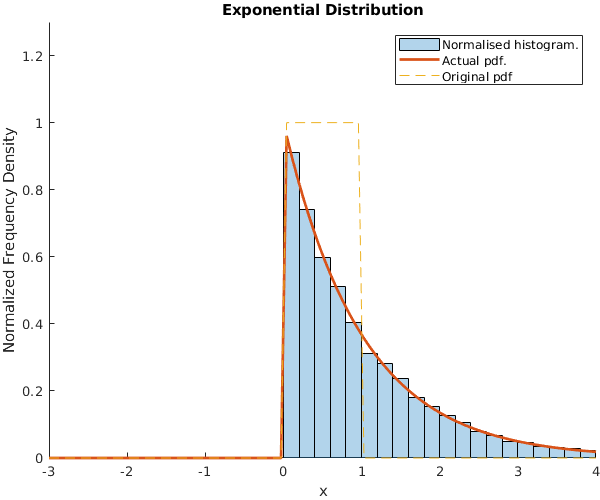

exponential_pdf = @(x) exp(-x) .* heaviside(x);
inverse_exponental_cdf = @(x) log(1 ./ (1 - x));

exponential_values = inverse_exponental_cdf(uniform_values + 0.5);

figure;
plot_histogram(exponential_values, exponential_pdf);
hold on;
plot(t, uniform_pdf(t - 0.5), '--', 'DisplayName', 'Original pdf');
title('Exponential Distribution');
print_fig('figures/exponential-histogram');

The graph shows histogramed values of exponentially distributed samples generated using the CDF method overlayed with plot of $e^{ -x }$. The histogrammed results strongly follow the exponential pdf.

## 2.4 Simulation from a 'Difficult' Density

For parameters $\alpha \in (0,2) (\alpha \ne 1)$ and $\beta \in [-1, +1]$, the the function `generate_alpha_stable()`  coverts samples from uniform and exponential distributions samples taken from the alpha stable distribution. The function is defined at the end of this document.

sample_count = N;
uniform = (rand(sample_count, 1) - 0.5) * pi;
expo = exprnd(1, [sample_count, 1]);        

plotdist = @(alpha, beta) plot_alpha_stable(alpha, beta, uniform, expo, 6);

`ksdesnity` estimates of distribution with$ \alpha=0.5,\,1.5$ and several values of $$\beta$:$.

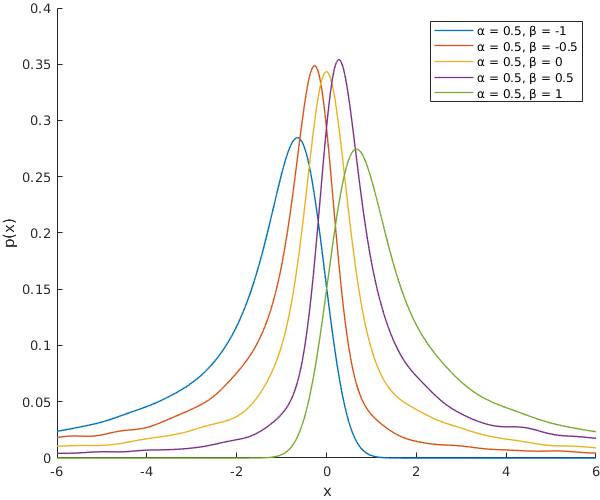

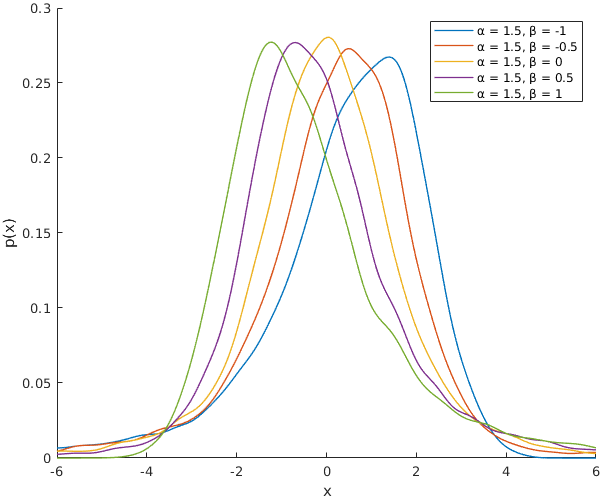

for alpha = [0.5, 1.5] 
    figure;
    hold on;
    legend;
    for beta = [-1, -0.5, 0, 0.5, 1]
       plotdist(alpha, beta); 
    end
    print_fig(sprintf('figures/alpha-%g-with-several-beta', alpha));
end

`ksdesnity` estimates of distribution with$\beta = 0$ and several values of $\alpha$.

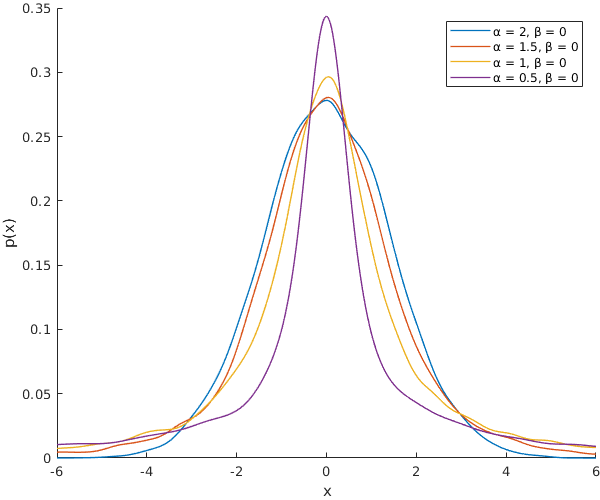

figure;
hold on;
legend;
for alpha = [2, 1.5, 1, 0.5]
    plotdist(alpha, 0);    
end
print_fig('figures/beta-0-with-several-large-alpha');

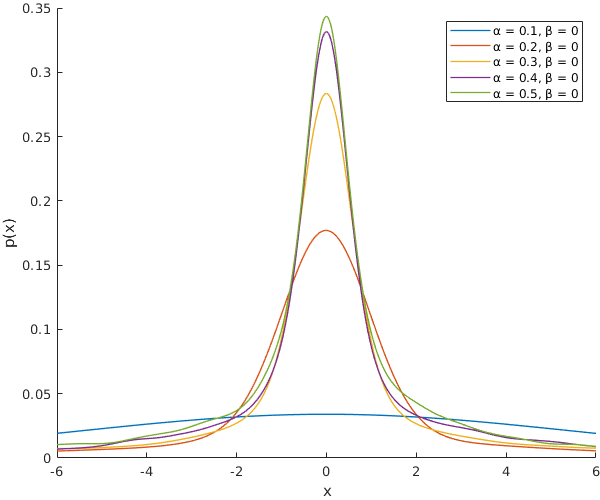


figure;
hold on;
legend;
for alpha = [0.1, 0.2, 0.3, 0.4, 0.5]
    plotdist(alpha, 0)
end

print_fig('figures/beta-0-with-several-large-alpha');

Parameters $\alpha$ and $\beta$ define the shape of the distribution. $\beta$ causes the distribution to be skewed; $\beta > 0$ causes the distribution to be very steep for the left side and then very shallow on the right side, as $\beta \to 1$the distribution becomes very heavy tailed. The opposite (heavy tail on the left side and sharp cut off on right side) is true for $\beta < 0.$

$\alpha$ controlls the variance of the distribution, $\alpha = 1/2$ creates a very sharp distribution which broadens out as $\alpha
$ decreases or increases. In the limit as $\alpha \to 0$ the distribution becomes $0$ everywhere (whilst integrating to unity).

## Function Definitions

function plot_ksdensity (values, pdf)
% plot_ksdensity  Plots ksdensity approximation of pdf overlayed
%   with the pdf defined by pdf.
    
    global graph_max t;
    hold on;
    
    [f,xi] = ksdensity(values);
    
    plot(xi, f, 'LineWidth', 2);
    plot(t, pdf(t), 'LineWidth', 2);
    
    legend('ksdensity approximation.', ...
        'Actual pdf.');
    ylabel('p(x)');
    xlabel('x');
    
    ylim([0, graph_max]);
    xlim([t(1) t(end)]);
    
    hold off;
end


function print_fig(file_name)
    % print_fig print current figure to file
    % called file_name.
    
    ax = gca;
    outerpos = ax.OuterPosition;
    ti = ax.TightInset; 
    left = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_width = outerpos(3) - ti(1) - ti(3);
    ax_height = outerpos(4) - ti(2) - ti(4);
    ax.Position = [left bottom ax_width ax_height];

    print(gcf, '-dpdf', strrep(file_name, '.', '_'));
end
